# **Smart Analysis**

**Demonstrating how to use intelligent analysis algorithms.**

**See also [opstool](https://opstool-doc.readthedocs.io/en/latest/src/analysis/smart_analysis.html#).**

clc; clear;

opsMAT = OpenSeesMatlab();
ops = opsMAT.opensees;

### Reinforced Concrete Frame Pushover Analysis

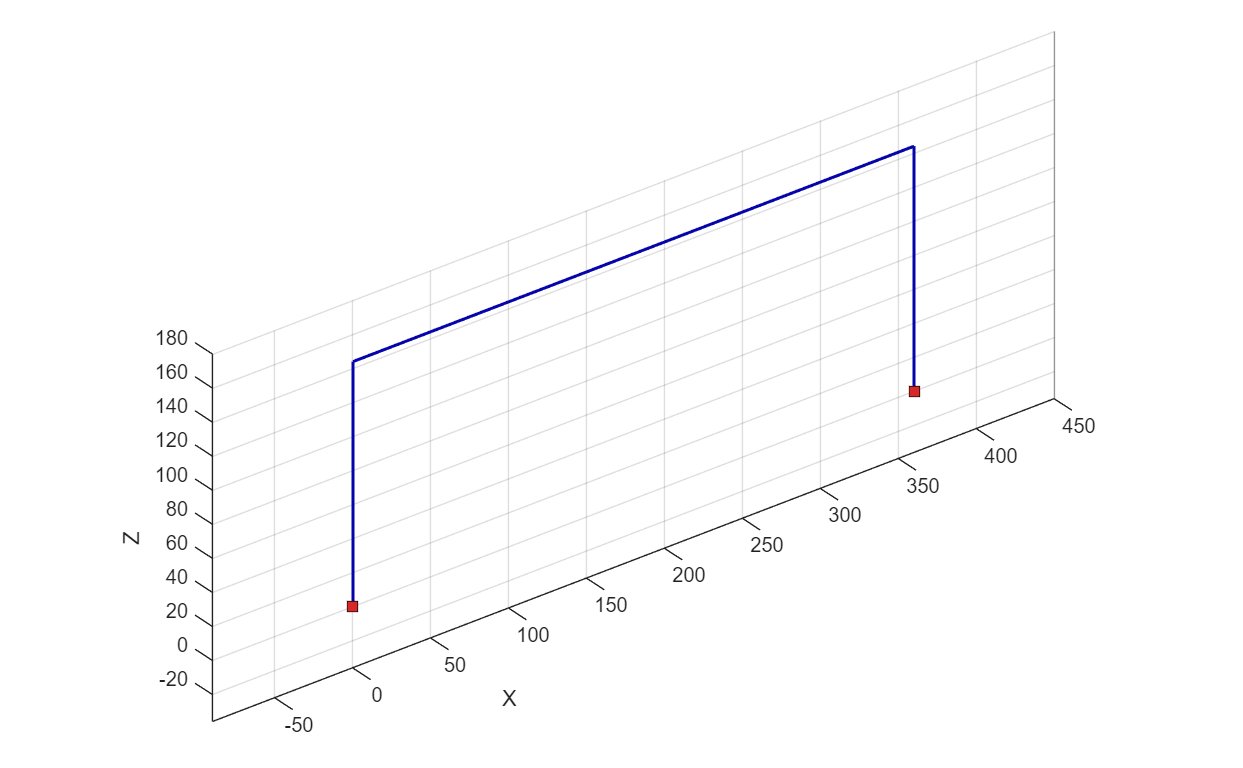

FEModel(ops);

figure;
opsMAT.vis.plotModel();

### **Smart Analysis**

#### **No fixed number of analyses**

% Set some parameters
dU = 0.1;  % Displacement increment
maxU = 45.0;  % Max displacement
ok = 0;
currentDisp = 0;

FEModel(ops);
gravityAnalysis(ops);
pushoverLoad(ops);

opsMAT.anlys.smartAnalyze.configure(...
    analysis="Static",...
    tryAddTestTimes=true, ...  % add test times to the analysis
    testIterTimesMore=[50, 100], ...
    tryAlterAlgoTypes=true, ...  % try different algorithms
    algoTypes=[40, 10, 20, 30], ... % algorithm types to try
    minStep=1e-6, ... % minimum step size for substepping
    debugMode=true, ... % False for progress bar, True for debug info
    printPer=100 ... % print every 100 steps
);

>>>✳️ OPSTOOL::SmartAnalyze:: Setting algorithm to KrylovNewton



node=3; dof=1; seg=dU;
while ok == 0 && currentDisp < maxU
    %  Perform the analysis one step at a time
    opsMAT.anlys.smartAnalyze.staticAnalyze(node, dof, seg);
    currentDisp = ops.nodeDisp(3, 1);
end

>>>✅ OPSTOOL::SmartAnalyze:: progress 100 steps. Time consumption: 1782.559 s.
>>>✅ OPSTOOL::SmartAnalyze:: progress 200 steps. Time consumption: 1782.623 s.
after: 10 iterations
 current EnergyIncr: 5.80578e-06 (max: 1e-10) 	Norm deltaX: 0.00017573, Norm deltaR: 0.672724
AcceleratedNewton::solveCurrentStep() -The ConvergenceTest object failed in test()
StaticAnalysis::analyze() - the Algorithm failed at step: 0 with domain at load factor 2.89496
OpenSees > analyze failed, returned: -3 error flag
>>>✳️ OPSTOOL::SmartAnalyze:: Adding test times to 50.
>>>✅ OPSTOOL::SmartAnalyze:: progress 300 steps. Time consumption: 1782.705 s.
>>>✅ OPSTOOL::SmartAnalyze:: progress 400 steps. Time consumption: 1782.764 s.
after: 10 iterations
 current EnergyIncr: 2.70125e-05 (max: 1e-10) 	Norm deltaX: 0.000819596, Norm deltaR: 0.253889
AcceleratedNewton::solveCurrentStep() -The ConvergenceTest 

opsMAT.anlys.smartAnalyze.reset();  % please make sure reset!

#### **Analysis of the fixed number of steps**

FEModel(ops);
gravityAnalysis(ops);
pushoverLoad(ops);

opsMAT.anlys.smartAnalyze.configure(...
    analysis="Static",...
    tryAddTestTimes=true, ...  % add test times to the analysis
    testIterTimesMore=[50, 100], ...
    tryAlterAlgoTypes=true, ...  % try different algorithms
    algoTypes=[40, 10, 20, 30], ... % algorithm types to try
    minStep=1e-6, ... % minimum step size for substepping
    debugMode=true, ... % False for progress bar, True for debug info
    printPer=100 ... % print every 100 steps
);

>>>✳️ OPSTOOL::SmartAnalyze:: Setting algorithm to KrylovNewton


H = 20.0;  % Reference lateral load
segs = opsMAT.anlys.smartAnalyze.staticStepSplit(maxU, dU);
data = zeros(numel(segs) + 1, 2);

for i = 1:numel(segs)
    opsMAT.anlys.smartAnalyze.staticAnalyze(node, dof, segs(i));

    data(i + 1, 1) = ops.nodeDisp(4, 1);
    data(i + 1, 2) = ops.getLoadFactor(2) * H;
end

>>>✅ OPSTOOL::SmartAnalyze:: progress 22.222 % . Time consumption: 0.113 s.
>>>✅ OPSTOOL::SmartAnalyze:: progress 44.444 % . Time consumption: 0.167 s.
after: 10 iterations
 current EnergyIncr: 5.80578e-06 (max: 1e-10) 	Norm deltaX: 0.00017573, Norm deltaR: 0.672724
AcceleratedNewton::solveCurrentStep() -The ConvergenceTest object failed in test()
StaticAnalysis::analyze() - the Algorithm failed at step: 0 with domain at load factor 2.89496
OpenSees > analyze failed, returned: -3 error flag
>>>✳️ OPSTOOL::SmartAnalyze:: Adding test times to 50.
>>>✅ OPSTOOL::SmartAnalyze:: progress 66.667 % . Time consumption: 0.232 s.
>>>✅ OPSTOOL::SmartAnalyze:: progress 88.889 % . Time consumption: 0.295 s.
after: 10 iterations
 current EnergyIncr: 2.70125e-05 (max: 1e-10) 	Norm deltaX: 0.000819596, Norm deltaR: 0.253889
AcceleratedNewton::solveCurrentStep() -The ConvergenceTest object faile

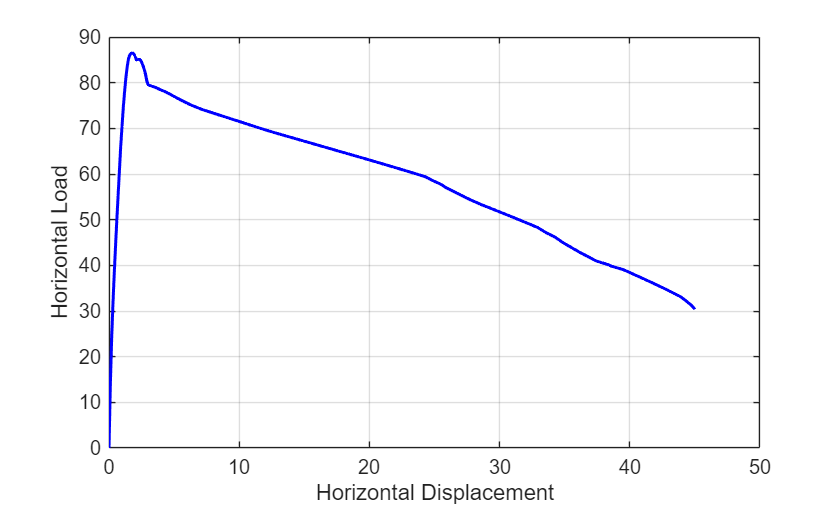

figure;
plot(data(:, 1), data(:, 2), 'LineWidth', 1.5, "Color", "blue");
xlabel('Horizontal Displacement');
ylabel('Horizontal Load');
grid on;

function FEModel(ops)
    ops.wipe();
    ops.model("basic", "-ndm", 3, "-ndf", 6);
    width = 360.0;
    height = 144.0;
    ops.node(1, 0.0, 0.0, 0.0);
    ops.node(2, width, 0.0, 0.0);
    ops.node(3, 0.0, 0.0, height);
    ops.node(4, width, 0.0, height);
    ops.fix(1, 1, 1, 1, 1, 1, 1);
    ops.fix(2, 1, 1, 1, 1, 1, 1);

    ops.uniaxialMaterial("Concrete01", 1, -6.0, -0.004, -5.0, -0.014);
    ops.uniaxialMaterial("Concrete01", 2, -5.0, -0.002, 0.0, -0.006);

    fy = 60.0;
    E = 30000.0;
    ops.uniaxialMaterial("Steel01", 3, fy, E, 0.01);

    % Define cross-section for nonlinear columns
    % ------------------------------------------
    colWidth = 15;
    colDepth = 24;
    cover = 1.5;
    As = 0.60;  % area of no. 7 bars
    % some variables derived from the parameters
    y1 = colDepth / 2.0;
    z1 = colWidth / 2.0;

    ops.section("Fiber", 1, "-GJ", 1000000);
    ops.patch("rect", 1, 10, 10, cover - y1, cover - z1, y1 - cover, z1 - cover);
    % Create the concrete cover fibers (top, bottom, left, right);
    ops.patch("rect", 2, 11, 1, -y1, z1 - cover, y1, z1);
    ops.patch("rect", 2, 11, 1, -y1, -z1, y1, cover - z1);
    ops.patch("rect", 2, 1, 10, -y1, cover - z1, cover - y1, z1 - cover);
    ops.patch("rect", 2, 1, 10, y1 - cover, cover - z1, y1, z1 - cover);
    % Create the reinforcing fibers (left, middle, right);
    ops.layer("straight", 3, 5, As, y1 - cover, z1 - cover, y1 - cover, cover - z1);
    ops.layer("straight", 3, 2, As, 0.0, z1 - cover, 0.0, cover - z1);
    ops.layer("straight", 3, 5, As, cover - y1, z1 - cover, cover - y1, cover - z1);

    % Define column elements
    % ----------------------
    ops.geomTransf("PDelta", 1, -1, 0, 0);
    % Number of integration points along length of element
    np = 5;
    % Lobatto integratoin
    ops.beamIntegration("Lobatto", 1, 1, np);
    eleType = "forceBeamColumn";
    ops.element(eleType, 1, 1, 3, 1, 1);
    ops.element(eleType, 2, 2, 4, 1, 1);

    % Define beam elment
    % -----------------------------
    ops.geomTransf("Linear", 2, 0.0, 0.0, 1.0);
    ops.element("elasticBeamColumn", 3, 3, 4, 360.0, 4030.0, 2015.0, 10000, 8640.0, 8640.0, 2);
end

function gravityAnalysis(ops)
    %  a parameter for the axial load
    P = 180.0;  % 10% of axial capacity of columns

    % Create a Plain load pattern with a Linear TimeSeries
    ops.timeSeries("Linear", 1);
    ops.pattern("Plain", 1, 1);

    % Create nodal loads at nodes 3 & 4
    %    nd  FX,  FY, MZ
    ops.load(3, 0.0, 0.0, -P, 0.0, 0.0, 0.0);
    ops.load(4, 0.0, 0.0, -P, 0.0, 0.0, 0.0);

    % Start of analysis generation
    % ------------------------------
    ops.system("BandGeneral");
    ops.constraints("Transformation");
    ops.numberer("RCM");
    ops.test("NormDispIncr", 1.0e-12, 10, 3);
    ops.algorithm("Newton");
    ops.integrator("LoadControl", 0.1);
    ops.analysis("Static");
    ops.analyze(10);
end

function pushoverLoad(ops)
    ops.loadConst("-time", 0.0)
    % Define lateral loads
    % --------------------
    % Set some parameters
    H = 10.0;  % Reference lateral load
    % Set lateral load pattern with a Linear TimeSeries
    ops.pattern("Plain", 2, 1);
    ops.load(3, H, 0.0, 0.0, 0.0, 0.0, 0.0);
    ops.load(4, H, 0.0, 0.0, 0.0, 0.0, 0.0);
end